# EPR UK 1000

clear; close all; clc;

## Dane:

ThermalPower = 4500e6;          %   [W]    moc cieplna reaktora
ActiveHeight = 4200/1000;       %   [m]    wysokość aktywnej części rdzenia
Pressure = 155;                 %   [bar]
NAssembly = 241;                %   [-]    liczba kaset paliwowych
NRods = 265;                    %   [-]    liczba prętów paliwowych w kasecie
TempInput = 295.6;              %   [°C]   temperatura wlotowa
WaterFlux = 75643000/3600;      %   [kg/s] strumień masy wody chłodzącej
AssemblyPitch = 214/1000;       %   [m]    skok siatki kaset
RodDiameter = 9.5/1000;         %   [m]    średnica pręta paliwowego
RodPitch = 11.26/1000;          %   [m]    skok siatki prętów w kasecie
UraniumMass = 527.5 * NAssembly;%   [kg]   masa materiału rozszczepialnego w rdzeniu
ExLength = 50/1000;             %   [m]    Długość ekstrapolacji
CladThickness = 0.57/1000;
GapThickness = 0.17/1000;
GapDiameter = RodDiameter - 2 * CladThickness;
PelletDiameter = 8.19/1000;

# Do zmianyyyyy!!!!

Pxy = 1.438;                    %   [-]    Wsp. promieniowy nierównomierności rozkładu      DO ZMIANY!!!!!!!!!!!!!

Te chyba nie są potrzebne

NeutronVelocity = 2200;         %   [m/s]  prędkość neutronów termicznych
SigmaU235 = 505e-24 * 1e-4;     %   [m]    efektywny mikroskopowy przekrój czynny na rozszczepienie dla neutronów termicznych dla U235
N_U235 = 1.3457e+20 * 1e6;      %   [1/m3] gęstość liczbowa/atomowa materiału rozszczepialnego
w_tot = 200 * 1e6 * 1.602e-19;  %   [J]    energia na jedno roszczepienie

## 1. Liniowa gęstość mocy

Liczba reakcji:

w_f = 0.95 * w_tot;                             %   [J]    odzyskiwalna energia
NReactions = ThermalPower / w_f;                %   [1/s]  liczba reakcji w rdzeniu

Objętość rdzenia:

AssemblyArea = AssemblyPitch^2;                         %   [m2]    powierzchnia przekroju poprzecznego jednej kasety
CoreVolume = AssemblyArea * ActiveHeight * NAssembly;   %   [m3]    objętość rdzenia

Szybkość reakcji:

Rf = NReactions * CoreVolume;                   %   [1/m3/s]    średnia szybkość reakcji w rdzeniu
Phi = Rf / (SigmaU235 * N_U235);                %   [1/m2/s]    średni strumień neutronów

Gęstość mocy rdzenia (objętościowa):

PowerDensityVol = ThermalPower / CoreVolume;    %   [W/m3]  średnia objętościowa gęstość mocy

Gęstość mocy rdzenia (właściwa):

PowerDensitySpec = ThermalPower / UraniumMass;  %   [W/kgU]     średnia właściwa gęstość mocy

Moc kasety:

AssemblyPower = ThermalPower / NAssembly;       %   [W]     średnia moc kasety

Moc pręta:

RodPower = AssemblyPower / NRods;               %   [W]     średnia moc pręta

Moc liniowa:

LengthTotal = ActiveHeight * NRods * NAssembly; %   [m]     całkowita długość prętów
LinHeatRate = ThermalPower / LengthTotal        %   [W/m]   średnia moc liniowa

LinHeatRate =         16776


## 1. Rozkład mocy wzdłuż kanału

ExHeight = ActiveHeight + 2 * ExLength;                                                                 %   [m]     wysokość rdzenia + 2 długości ekstrapolacji
ChannelPower = ThermalPower / (NAssembly * NRods);                                                      %   [W]     średnia moc kanału
AvgChannelPowerMax = pi * ChannelPower / (ExHeight * 2 * sin((pi * ActiveHeight) / (2 * ExHeight)));    %   [W/m]     maksymalna moc dla średniego kanału
HotChannelPowerMax = AvgChannelPowerMax * Pxy;                                                          %   [W/m]     maksymalna moc dla gorącego kanału

rozkład mocy w kanałach:

z = linspace(-ActiveHeight/2, ActiveHeight/2, 100);
AvgChannelPower =  AvgChannelPowerMax * cos(pi * z / ExHeight);     %   rozkład mocy liniowej średniego kanału
HotChannelPower =  HotChannelPowerMax * cos(pi * z / ExHeight);     %   rozkład mocy liniowej gorącego kanału

Wykres:

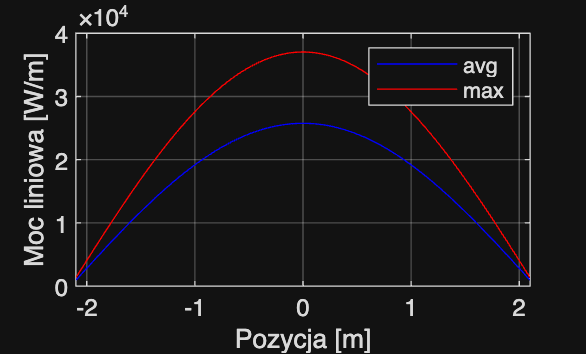

figure(1); grid on; box on; hold on;
ylabel("Moc liniowa [W/m]")
xlabel("Pozycja [m]")
plot(z, AvgChannelPower, "b-")
plot(z, HotChannelPower, "r-")
legend('avg', 'max')
hold off;

## 2. Rozkład temperatury w kanale

Cp = 1000 * XSteam('Cp_pT', Pressure, TempInput);

WaterFluxChannel = WaterFlux / (NAssembly * NRods);                     %   [kg/s]      strumień masy wody w kanale
TempAvgChannel = TempInput + (AvgChannelPowerMax/(WaterFluxChannel * Cp)) * (ExHeight / pi) * (sin(pi * z / ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));     %   rozkład temperatury w kanale średnim
TempHotChannel = TempInput + (HotChannelPowerMax/(WaterFluxChannel * Cp)) * (ExHeight / pi) * (sin(pi * z / ExHeight) + sin(pi * ActiveHeight / (2 * ExHeight)));     %   rozkład temperatury w kanale średnim

Wykres:

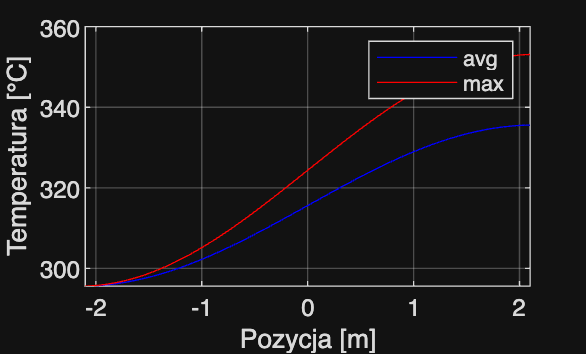

figure(2); grid on; box on; hold on;
xlabel("Pozycja [m]")
ylabel("Temperatura [°C]")
plot(z, TempAvgChannel, "b-")
plot(z, TempHotChannel, "r-")
legend('avg', 'max')
hold off;

## 3. Rozkład temperatury zewnętrznej koszulki

Średnica hydrauliczna:

FlowArea = RodPitch^2 - (pi / 4) * RodDiameter^2;
WetPerimeter = pi * RodDiameter;
HydraulicDiameter = 4 * FlowArea / WetPerimeter

HydraulicDiameter =     0.0074927


G = WaterFluxChannel / FlowArea;

Liczba Reynoldsa i liczba Prandtla:

Mu = XSteam('my_pT', Pressure, TempInput);
Re = G * HydraulicDiameter / Mu

Re =    4.8869e+05


k = XSteam('tc_pt', Pressure, TempInput);
Pr = Cp * Mu / k

Pr =       0.85156


Liczba Nusselta:

NuDB = 0.023 * (Re^(0.8)) * (Pr^0.4)

NuDB =        767.44


B = (4 / pi) * (RodPitch / RodDiameter)^2 - 1;
NuMarkoczy = (1 + 0.91 * (Re^(-0.1)) * (Pr^0.4) * (1 - 2 * exp(-B))) * NuDB

NuMarkoczy =        783.54


Współczynnik przejmowania ciepła:

hDB = NuDB * k / HydraulicDiameter;
hMarkoczy = NuMarkoczy * k / HydraulicDiameter;
h = hMarkoczy

h =         59355


Przyrost temperatury przepływ - paliwo:

AvgDeltaTempWall = AvgChannelPower ./ (pi * RodDiameter * h);
HotDeltaTempWall = HotChannelPower ./ (pi * RodDiameter * h);

Temperatura powierzchni koszulki:

TempAvgCladOuter = TempAvgChannel + AvgDeltaTempWall;
TempHotCladOuter = TempHotChannel + HotDeltaTempWall;

Wykres:

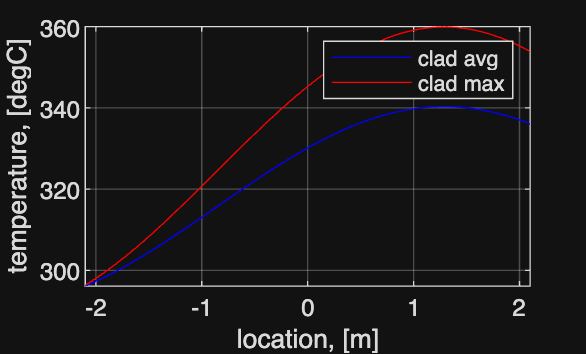

figure(3); grid on; box on; hold on;
plot(z, TempAvgCladOuter, '-b')
plot(z, TempHotCladOuter, '-r')
legend('clad avg', 'clad max')
xlabel('location, [m]')
ylabel('temperature, [degC]')
hold off;

AvgTempAvgCladOuter = mean(TempAvgCladOuter)

AvgTempAvgCladOuter =        324.97


max(TempAvgCladOuter)

ans =        340.32


max(TempHotCladOuter)

ans =        359.91


min(TempAvgCladOuter)

ans =        296.13


min(TempHotCladOuter)

ans =        296.36


## 4. Rozkład temperatury wewnętrznej koszulki

Przewodność cieplna koszulki:

kClad = k_ZR(AvgTempAvgCladOuter)

kClad =        12.935


Przyrosty temperatury:

AvgDeltaTempCladInner = (AvgChannelPower / (2 * pi * kClad)) * log(GapDiameter/PelletDiameter);
HotDeltaTempCladInner = (HotChannelPower / (2 * pi * kClad)) * log(GapDiameter/PelletDiameter);

Wykres:

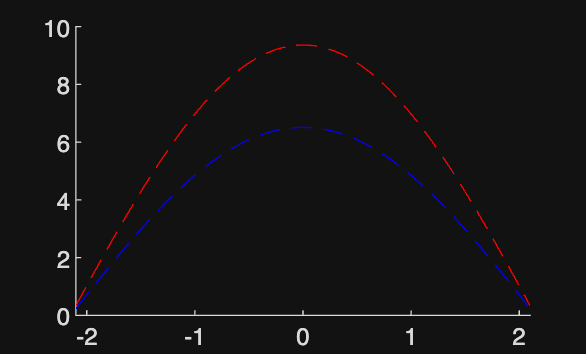

figure(4); grid; box; hold on;
plot(z, AvgDeltaTempCladInner, '--b')
plot(z, HotDeltaTempCladInner, '--r')
hold off;

Temperatury:

TempAvgCladInner = TempAvgCladOuter + AvgDeltaTempCladInner;
TempHotCladInner = TempHotCladOuter + HotDeltaTempCladInner;

Wykres:

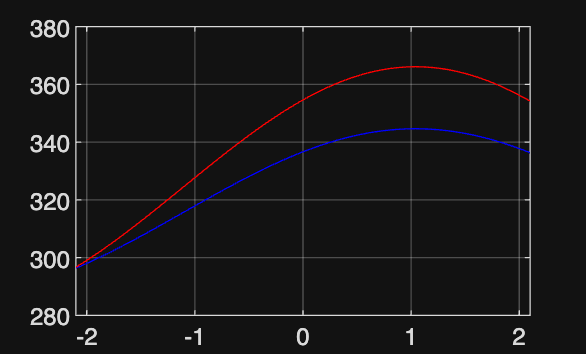

figure(5); grid on; box on; hold on;
plot(z, TempAvgCladInner, '-b')
plot(z, TempHotCladInner, '-r')
hold off;

max(TempAvgCladInner)

ans =        344.63


max(TempHotCladInner)

ans =         366.1


min(TempAvgCladInner)

ans =        296.37


min(TempHotCladInner)

ans =        296.71


Wykres łączny:

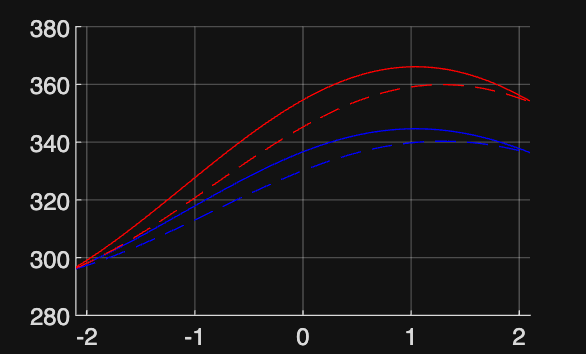

figure (6); grid on; box; hold on;
plot(z, TempAvgCladInner, '-b')
plot(z, TempHotCladInner, '-r')
plot(z, TempAvgCladOuter, '--b')
plot(z, TempHotCladOuter, '--r')
hold off;

## 5. Rozkład temperatury na powierzchni paliwa